% Cost, Yield and Supply Given for each item where airdrops
% Standard_Blaster = [0,10,896] and Jetpack = [0,40,2325] dont have a $BNTY
% cost thus are not included in the ROI calculations. There are 12 in total

% Primary
Charge_Rifle = [12000,50,450];
Jigsaw_Rifle = [7500,35,377];
% Secondary
Jannus_Mods_HB = [5000,25,502];
Berine_Blaster = [7500,30,386];
% Melee
Alkavir_Shortsword = [10000,50,500];
Velurian_Sabre = [15000,100,60];
Rayblade = [7500,50,300];
% Misc:
Galaxy_Mapper = [3000,20,250];
JannusTech_Flamethrower = [4000,30,200];
Spider_Brain = [500,5,2000];

% Items are ordered in terms of the x-axis component from lowest cost to
% highest as the linear regression models requires data to be continuous in
% order to not have jumps in the modelling results
Item_Costs = [Spider_Brain(1),Galaxy_Mapper(1),JannusTech_Flamethrower(1),Jannus_Mods_HB(1),Rayblade(1),Berine_Blaster(1),Jigsaw_Rifle(1),Alkavir_Shortsword(1),Charge_Rifle(1),Velurian_Sabre(1)]

Item_Costs =          500        3000        4000        5000        7500        7500        7500       10000       12000       15000


Item_Yields = [Spider_Brain(2),Galaxy_Mapper(2),JannusTech_Flamethrower(2),Jannus_Mods_HB(2),Rayblade(2),Berine_Blaster(2),Jigsaw_Rifle(2),Alkavir_Shortsword(2),Charge_Rifle(2),Velurian_Sabre(2)]

Item_Yields =      5    20    30    25    50    30    35    50    50   100


Item_Number = [Spider_Brain(3),Galaxy_Mapper(3),JannusTech_Flamethrower(3),Jannus_Mods_HB(3),Rayblade(3),Berine_Blaster(3),Jigsaw_Rifle(3),Alkavir_Shortsword(3),Charge_Rifle(3),Velurian_Sabre(3)]

Item_Number =         2000         250         200         502         300         386         377         500         450          60


% Creates a non-linear regression model fitting the item yields compared to
% their cost and and assigns 2 degrees of freedom using the custom
% "modelfunc" function. This mimics the form "y = m*x + c" where "c" is
% purposely ignored as the gradient results in the ROI
start = [180]

start = 180

mdl = fitnlm(Item_Yields,Item_Costs,@modelfunc,start);
X = linspace(0,15000,15000)

X = 	1.0e+04 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


ROI = Item_Costs./Item_Yields

ROI =   100.0000  150.0000  133.3333  200.0000  150.0000  250.0000  214.2857  200.0000  240.0000  150.0000



% Plots the items with data labels on a graph with a colour coded region
% from the min ROI to the max ROI depicting visually for each item data
% point how well it lies in the region
figure(1)
hold on
for LoopVar1 = min(ROI) : max(ROI)
    plot(X,LoopVar1 * X,'color',[(LoopVar1-min(ROI))/(max(ROI)-min(ROI)) (1-(LoopVar1-min(ROI))/(max(ROI)-min(ROI))) 0])
end
% Plots the main body of the graph
title('Mint Price vs Yield analysis for Black Marke Items')
xlabel('Item Yield')
ylabel('Black Market BNTY Price')
labels = {'Spider Brain','Galaxy Mapper','Flamethrower','JM HB44','Rayblade','Berine','Jigsaw','Shortsword','Charge Rifle','Velurian Sabre'}

labels = 1×10 cell array
    {'Spider Brain'}    {'Galaxy Mapper'}    {'Flamethrower'}    {'JM HB44'}    {'Rayblade'}    {'Berine'}    {'Jigsaw'}    {'Shortsword'}    {'Charge Rifle'}    {'Velurian Sabre'}


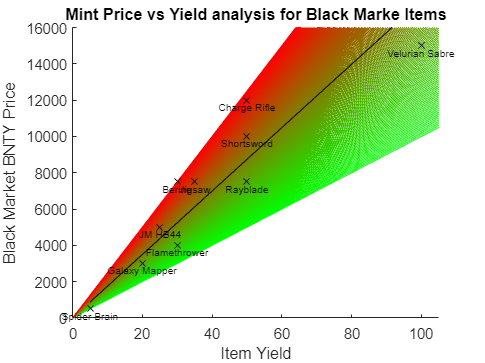

plot(Item_Yields,Item_Costs,"kx")
plot(Item_Yields,predict(mdl,Item_Yields'),'k')
text(Item_Yields,Item_Costs,labels,'FontSize',7,'VerticalAlignment','top','HorizontalAlignment','center')
ylim([0,16000])
xlim([0,105])


% Injects the values for jetpacks and standard blasters obtained thanks to
% Zach using solscan and looking at the token adresses.
Item_Number = [Item_Number 896 2325];
Item_Yields = [Item_Yields 40 10];
labels = [labels 'Jetpack' 'Standard Blaster'];
% Plots the item's total emissions by finding the product of their volume
% and yield then visualises it against all other items in the collection
figure(2)
hold on
title('Emission of BNTY from Item Staking (BNTY)')
ylabel('Cumulative Staking Reward')
Emissions = Item_Number.* Item_Yields;
Total_BNTY = sum(Emissions)

Total_BNTY = 185915

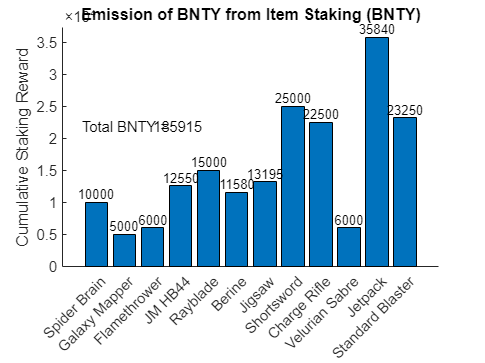

X2 = linspace(1,12,12);
bar(Emissions)
xticklabels(labels)
xticks(X2)
ylim([0,max(Emissions)+1500])
text(X2,Emissions,string(Emissions),'FontSize',9,'VerticalAlignment','bottom','HorizontalAlignment','center')
text(0.5,22000,'Total BNTY ='),text(3,22000,string(Total_BNTY))


% Determines the number of hunters earning BNTY to determine a hypotetical
% max possible yield for the whole project
Staked_Hunters = round(0.7964*5555) 

Staked_Hunters = 4424

Total_BNTY = Total_BNTY + Staked_Hunters * 100

Total_BNTY = 628315

Currnet_Hunter = 4768

Currnet_Hunter = 4768

Not_Staked = Currnet_Hunter - Staked_Hunters

Not_Staked = 344

function [ y ] = modelfunc(b,x)
y = b(1) * x;
end